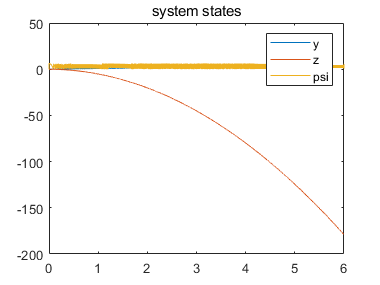

clc; 
clear all; close all;
x0 = [0;0;0;1;0;0]; % x0 is the intial state of the system

tspan=[0; 6]; % simulation time



[t,x] = ode45(@sys_dynamics,tspan,x0);
n=size(t,1);
line0=zeros(n,1);

 % plot the simulation data
 figure; plot(t,x(:,1),t,x(:,2),t,mod(x(:,3),pi*2)); legend('y','z','psi'); title('system states'); 

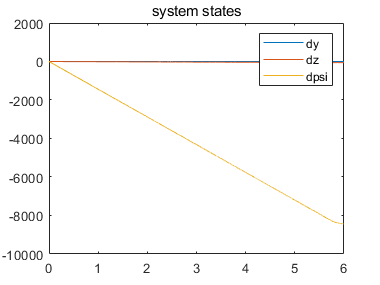

figure(2); plot(t,x(:,4),t,x(:,5),t,x(:,6)); legend('dy','dz','dpsi'); title('system states'); 

function dx=sys_dynamics(t,x)

dx=zeros(6,1);
dx(1)=x(4);
dx(2)=x(5);
dx(3)=x(6);
dx(4:6)=[0;-9.81;0]+[-sin(x(3)) 0;cos(x(3)) 0;0 1200]*controller(x);
end


function u=controller(x)
u(1)=9.81/cos(x(3));
u(2)=
%max dw=2
if abs(u(1))<-1
end
if abs(u(2))>2/1200
    u(2)=2/1200;
end
end